# Menu Button

This widget provides a button that opens to a menu. You can add custom uimenu items to it.

Create a figure with a grid layout:

figObj = uifigure("Position",[100 100 250 150]);
gridObj = uigridlayout(figObj,"BackgroundColor",[.6 .8 1]);
gridObj.RowHeight = {'fit','1x'};
gridObj.ColumnWidth = {'1x','fit'};

Create and configure the widget:

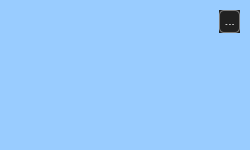

mbWidget = wt.MenuButton(gridObj);
mbWidget.Layout.Column = 2;

mbWidget.MenuSelectedFcn = @(src,evt)disp(evt);

names = ["Item 1","Item 2","Item 3"];
menuItems = mbWidget.addMenuItems(names);
menuItems(3).Separator = "on"; % Add a horizontal separator line

Pressing the button will automatically open the menu.

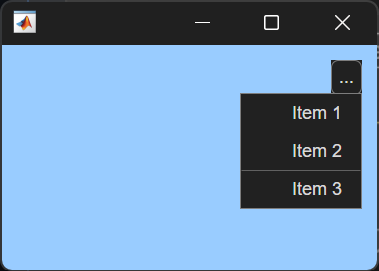

*Copyright 2025 The MathWorks, Inc.*